# sys ts

## init env

clc;
clear all;
close all;


% ts


$$  P_2(s)=\frac{100}{(s+1)(0.025s+1)^2},\quad P_1(s)=\frac{100}{(s+1)}
$$


% P1
zeros = [];
poles =[-1];
gain = 100;
sys_p1 = zpk(zeros,poles,gain)

sys_p1 =
 
   100
  -----
  (s+1)
 
Continuous-time zero/pole/gain model.
Model Properties



% P2
zeros2 = [];
poles2 =[-40 -40];
gain2 = 40^2;
sys_p2 = sys_p1 * zpk(zeros2,poles2,gain2)

sys_p2 =
 
     1.6e+05
  --------------
  (s+1) (s+40)^2
 
Continuous-time zero/pole/gain model.
Model Properties


## open step

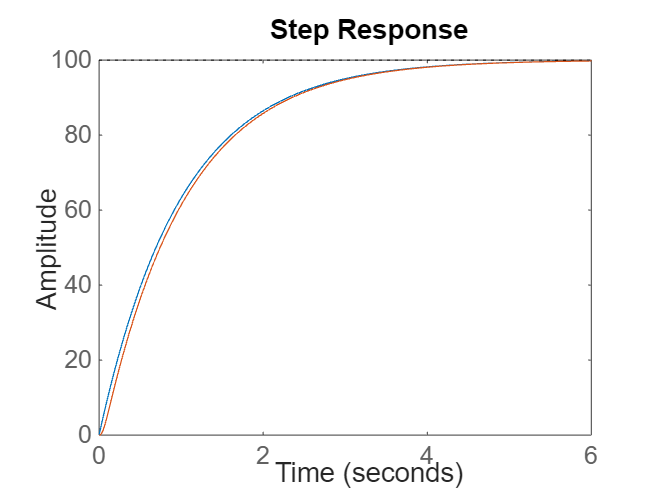


step(sys_p1,sys_p2)

## close step

% close feedback loops transfer function


$$$\mathrm{H}=\frac{\mathrm{G}}{1+\mathrm{GK}}$$$


K=1;
H1 = feedback(sys_p1,K)

H1 =
 
    100
  -------
  (s+101)
 
Continuous-time zero/pole/gain model.
Model Properties


H2 = feedback(sys_p2,K)

H2 =
 
              1.6e+05
  -------------------------------
  (s+83.93) (s^2 - 2.925s + 1926)
 
Continuous-time zero/pole/gain model.
Model Properties


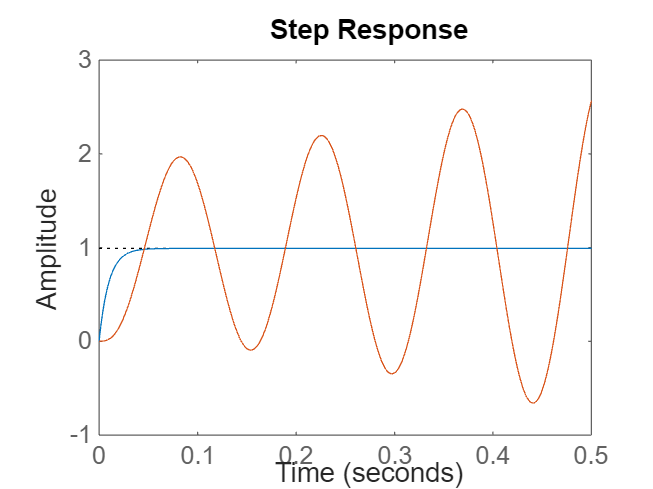

step(H1,H2,0.5)